Nbits = 1e6;
in = randi([0, 1], [Nbits, 1])*2-1;

Transmitter

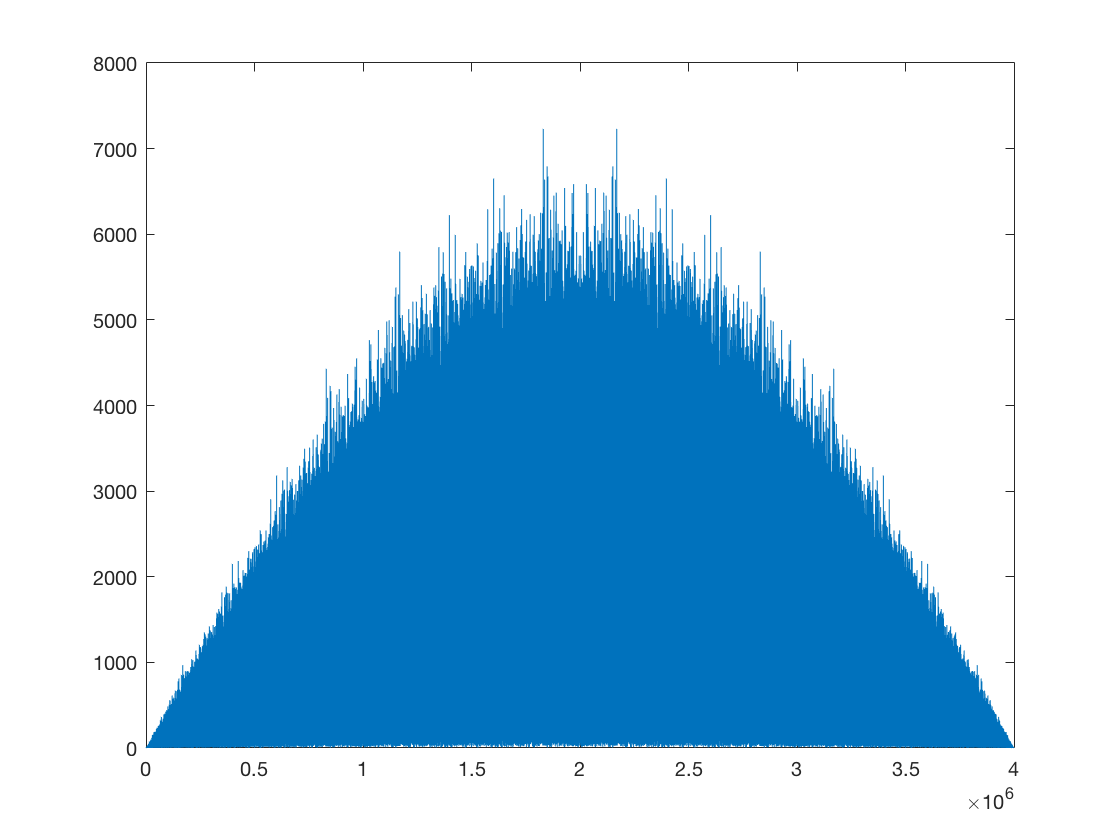

k = 2;
SpS = 2*k;
BpS = 1;
R_s = 1;
R_b = R_s * BpS;
B_sim = SpS * R_s;
v_t = zeros(Nbits*SpS, 1);

d_f = 1/Nbits;
f = (-(SpS/2):d_f:(SpS/2-d_f))';
f_p = 1.5;

% RZ
for a=0:Nbits-1
    for b=1:SpS/2
        v_t(a*SpS+b) = in(a+1);
    end
end
figure(1)
plot(1:Nbits*SpS, fftshift(abs(fft(v_t))))

Calcolo errori a diversi BER

err_arr = zeros(11, 1);
for www=2:12

Rumore Gaussiano Bianco

    EbN0 = (10^(www/10));
    P = mean(abs(in.^2));
    N0 = P/(EbN0*R_b);
    sigma = sqrt((N0/2)*B_sim);
    noise = sigma*randn(Nbits*SpS, 1);
    in_n = v_t+noise;

Filtro di Ricezione

    H_rx = 1./(1+1i*(f/f_p));
    X_f = fft(in_n);
    Y_f = H_rx .* X_f;
    y = ifft(Y_f);

Sampling & Decision

Vediamo su quale bit è meglio campionare

    BERs = zeros(SpS, 1);
    for bit = 1:SpS
        r = y(bit:SpS:end) > 0;
        r = 2*r-1;
        err = in ~= r;
        BERs(bit) = sum(err)/Nbits;
    end
    BERs
    [m, i] = min(BERs);
    i

Scegliamo di campionare sul bit i-esimo (è sempre il primo)

    r = y(i:SpS:end) > 0;
    r = 2*r-1;

Conteggio errori

    err = in ~= r;
    err_arr(www-1) = sum(err)/Nbits;
end

BERs =     0.1965
    0.3824
    0.6933
    0.5517


i = 1

BERs =     0.1689
    0.3692
    0.7132
    0.5574


i = 1

BERs =     0.1420
    0.3549
    0.7360
    0.5652


i = 1

BERs =     0.1161
    0.3384
    0.7593
    0.5718


i = 1

BERs =     0.0916
    0.3209
    0.7832
    0.5789


i = 1

BERs =     0.0688
    0.3023
    0.8084
    0.5872


i = 1

BERs =     0.0494
    0.2815
    0.8336
    0.5960


i = 1

BERs =     0.0337
    0.2616
    0.8590
    0.6056


i = 1

BERs =     0.0212
    0.2393
    0.8825
    0.6130


i = 1

BERs =     0.0127
    0.2169
    0.9039
    0.6230


i = 1

BERs =     0.0069
    0.1948
    0.9243
    0.6318


i = 1

Plotting

err_arr

err_arr =     0.1965
    0.1689
    0.1420
    0.1161
    0.0916
    0.0688
    0.0494
    0.0337
    0.0212
    0.0127


figure(2)
semilogy(2:12, err_arr, 'ro')
hold on

Andamento teorico

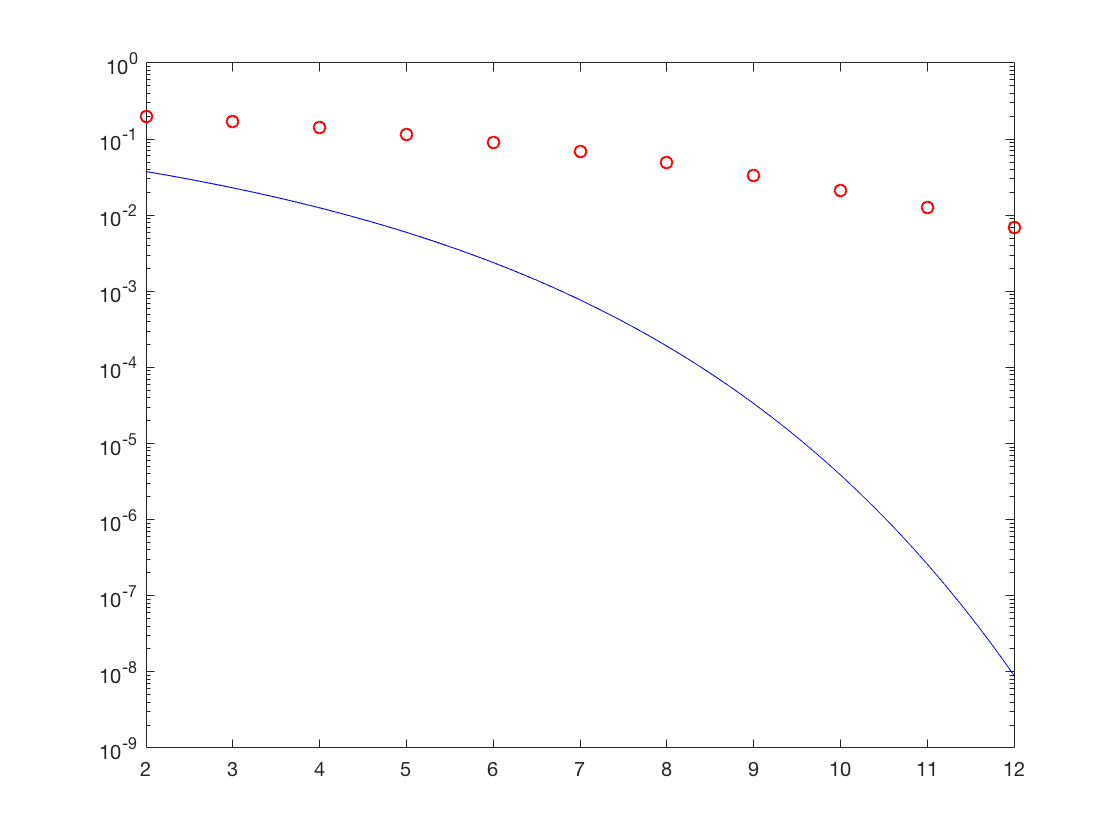

EbN0 = 2:0.1:12;
BER = 0.5*erfc(sqrt(10.^(EbN0/10)));
semilogy(EbN0, BER, 'b-')

hold off

Diagramma ad occhio

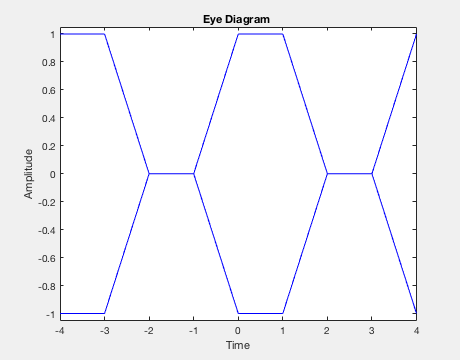

figure(3)
eyediagram(v_t(1:2000*SpS), 2*SpS, 2*SpS);

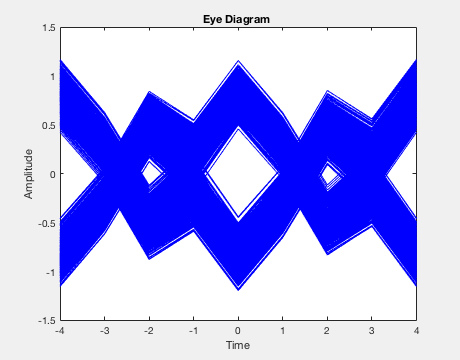



X_f_nn = fft(v_t);
Y_f_nn = H_rx .* X_f_nn;
y_nn = real(ifft(Y_f_nn));
figure(4)
eyediagram(y_nn(1:2000*SpS), 2*SpS, 2*SpS);